# Procedure 1 for Acrobot system with scaling

clear; close all; clc;
set(0,'DefaultLineLineWidth',2.5) 
set(0,'defaultfigurecolor',[1 1 1])

## 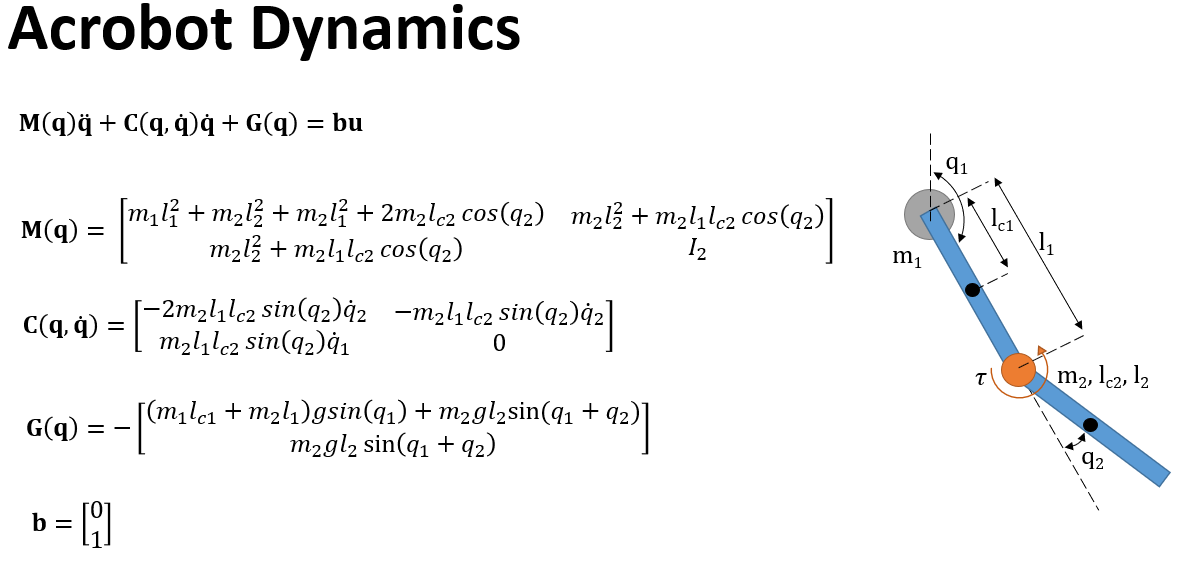

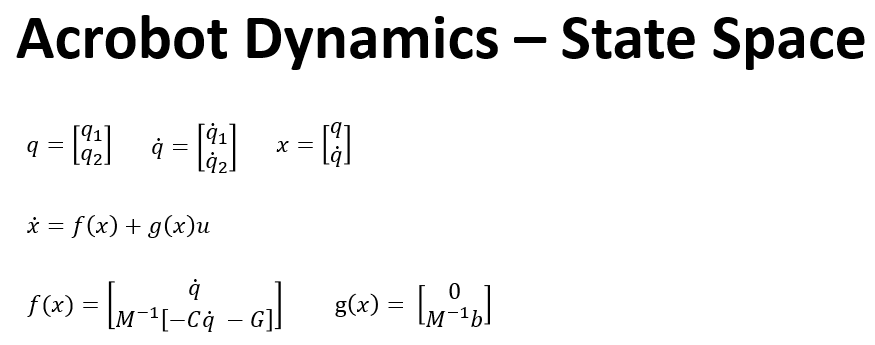

f = @Acrobot_F;
g = @Acrobot_g;

## 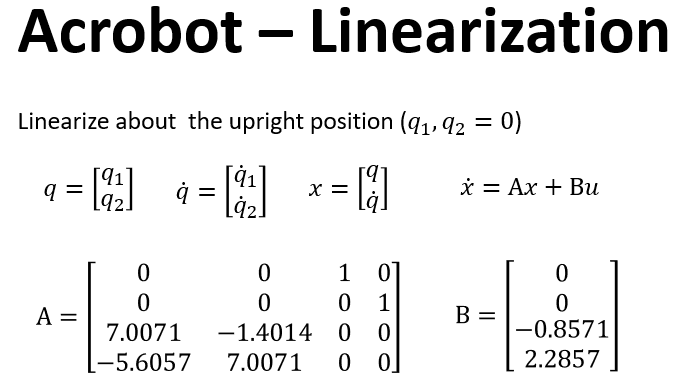

n=4; % dimension
x = sym('x',[n;1]);
u = sym('u',[1;1]);
x0 = [0;0;0;0];

A = double(subs(jacobian(f(0,x,0),x),x,x0)); 
B = double(subs(jacobian(f(0,x0,u),u),u,0));
%linear eigenfunctions realization from complex eigenfunctions
[~,D1,W1] = eig(A);
[W, D] = cdf2rdf(W1, D1);

## Plot the uncontrolled response

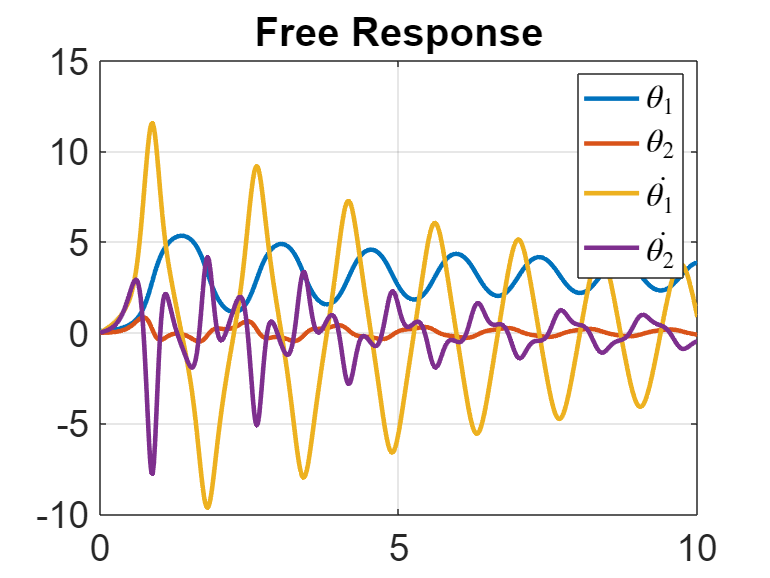

n=4; % dimension
tSpan = 0:0.02:10; ic = [0.1,0,0,0]';
options = odeset('RelTol',1e-9,'AbsTol',1e-300);
[T, x_uncontrolled] = ode45(@(t,x)f(0, x, 0), tSpan, ic,options);
close all
figure()
%subplot(1,2,1)
plot(T, x_uncontrolled(:,1:n))
grid on;
title('Free Response')
set(gca,'fontsize',20)
LEG = legend('$\theta_1$', '$\theta_2$', '$\dot{\theta_1}$','$\dot{\theta_2}$');
set(LEG,'interpreter','latex');

## Parameters setup

Dom1 = [-2*pi 2*pi]; %Domain for q1 q2
Dom2 = [-5 5]; %Domain for q1_dot q2_dot
domain1 = Dom1(2)-Dom1(1);
domain2 = Dom2(2)-Dom2(1);

## Collect random initial conditions

numICs = 1e4; %initial coditions
X1 = (rand(2,numICs)*2*Dom1(2) - Dom1(2));
X2 = (rand(2,numICs)*2*Dom2(2) - Dom2(2));
X=[X1;X2];

## Scale the F(z) and Ez data points

F_z = f(0, X, 0);
F_z_scaled = [F_z(1:2,:)./domain1;F_z(3:4,:)./domain2];

E = A;
E_z = E*X;
E_z_scaled = [E_z(1:2,:)./domain1;E_z(3:4,:)./domain2];

X_scaled = [X(1:2,:)./domain1;X(3:4,:)./domain2];

## Selet basis functions to approximate h(x)

order = 3; %order poly
[Psi, DPsi] = monomial_basis(order, n);

$$Psi = \left(\begin{array}{cccccccccccccccccccccccccccccccccc} x_{1} & x_{2} & x_{3} & x_{4} & {x_{4}}^{2} & x_{3}\,x_{4} & {x_{3}}^{2} & x_{2}\,x_{4} & x_{2}\,x_{3} & {x_{2}}^{2} & x_{1}\,x_{4} & x_{1}\,x_{3} & x_{1}\,x_{2} & {x_{1}}^{2} & {x_{4}}^{3} & x_{3}\,{x_{4}}^{2} & {x_{3}}^{2}\,x_{4} & {x_{3}}^{3} & x_{2}\,{x_{4}}^{2} & x_{2}\,x_{3}\,x_{4} & x_{2}\,{x_{3}}^{2} & {x_{2}}^{2}\,x_{4} & {x_{2}}^{2}\,x_{3} & {x_{2}}^{3} & x_{1}\,{x_{4}}^{2} & x_{1}\,x_{3}\,x_{4} & x_{1}\,{x_{3}}^{2} & x_{1}\,x_{2}\,x_{4} & x_{1}\,x_{2}\,x_{3} & x_{1}\,{x_{2}}^{2} & {x_{1}}^{2}\,x_{4} & {x_{1}}^{2}\,x_{3} & {x_{1}}^{2}\,x_{2} & {x_{1}}^{3} \end{array}\right)$$

%[Psi, DPsi] = bernstein_basis(order, n, 1);
Psi = Psi(n+1:end); %remove linear part
Nbs = length(Psi);

x1 = sym('x',[n,1]);
DPsi = jacobian(Psi,x1);

Psi = matlabFunction(Psi,'Vars',{x1});
DPsi = matlabFunction(DPsi,'Vars',{x1});

## Solve the least squares problem to estimate U in the scaled domain

G_z = Psi(X_scaled);

Df_z = zeros(Nbs,1);

for i=1:size(X_scaled,2)
    Df_z(:,i) = DPsi(X_scaled(:,i))*F_z_scaled(:,i);
end

% YALMIP 
U_scaled = sdpvar(n,Nbs);
Objective =  norm(U_scaled*Df_z + F_z_scaled - E*U_scaled*G_z - E_z_scaled, 'fro'); 
Constraints = [];
opt = sdpsettings('solver','gurobi','verbose',1,'cachesolvers',1);
sol = optimize(Constraints,Objective,opt);

Set parameter Username
Academic license - for non-commercial use only - expires 2023-02-11
Warning for adding variables: zero or small (< 1e-13) coefficients, ignored
Gurobi Optimizer version 9.5.0 build v9.5.0rc5 (win64)
Thread count: 4 physical cores, 8 logical processors, using up to 8 threads
Optimize a model with 40001 rows, 40122 columns and 3499974 nonzeros
Model fingerprint: 0x2c3388e3
Model has 1 quadratic constraint
Coefficient statistics:
  Matrix range     [1e-13, 2e+01]
  QMatrix range    [1e+00, 1e+00]
  Objective range  [1e+00, 1e+00]
  Bounds range     [0e+00, 0e+00]
  RHS range        [4e-04, 5e+01]
Presolve removed 1 rows and 1 columns
Presolve time: 1.88s
Presolved: 40000 rows, 40121 columns, 3499972 nonzeros
Presolved model has 1 second-order cone constraint
Ordering time: 0.14s

Barrier statistics:
 Dense cols : 121
 Free vars  : 120
 AA' NZ     : 3.500e+06
 Factor NZ  : 4.007e+06 (roughly 60 MB of memory)
 Factor Ops : 4.473e+08 (less than 1 second per iteration)


U_scaled = value(U_scaled)

U_scaled =    -0.0369    0.0067    0.0192    0.0014   -0.0171    0.0260    0.0009    0.0203   -0.0064   -0.0272   -0.0773    0.0680    0.1074   -0.0215   -0.1388   -0.1920    0.0022    0.2230   -0.0313   -0.0113   -1.9437    0.0507   -2.7514   -0.2223    0.1961   -1.8704    0.0709   -0.1064   -0.0037   -4.4394
   -0.0079    0.0207    0.0012    0.0040    0.0053   -0.0055   -0.0005   -0.0142    0.0186   -0.0060    0.1359    0.0150    0.0285   -0.0361   -2.1438    0.1194   -1.9974   -0.6501    0.0242   -4.3708    0.0223   -0.0793    0.1600    0.1449   -0.2759    0.0372   -0.1022    0.1641   -1.9243   -0.0377
    0.0011   -0.0129    0.0161    0.0414   -0.0051   -0.0000   -0.0051   -0.0433    0.0000   -0.0000   -0.1105   -1.6995    0.0421   -2.1895    0.3549   -0.2268    0.1560   -0.0269   -1.4884   -0.0000   -0.1769    0.2689   -0.1694   -2.9769   -0.0060   -0.0000   -0.0030  -10.5982   -0.0000   -0.0000
    0.0032    0.0038   -0.0113   -0.0088    0.0148    0.0000    0.0148   -0.0095   -0.

## Map U back to the origonal domain

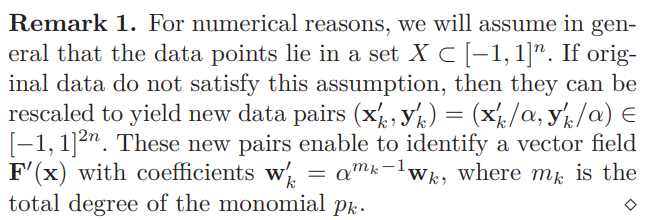

Mauroy, A., & Goncalves, J. (2019). Koopman-based lifting techniques for nonlinear systems identification. *IEEE Transactions on Automatic Control. *(https://arxiv.org/pdf/1709.02003.pdf) 

monomial_degrees = polynomialDegree(Psi(x));

U = [];
alpha = [domain1; domain2];

for k = 1:size(monomial_degrees,1)
    m_k = monomial_degrees(k);
    unscale = alpha.^(m_k-1);
    unscale_factor = [unscale;unscale];
    U(:,k) = U_scaled(:,k)./unscale_factor;
end
U

U =    -0.0029    0.0005    0.0015    0.0001   -0.0014    0.0021    0.0001    0.0016   -0.0005   -0.0022   -0.0005    0.0004    0.0007   -0.0001   -0.0009   -0.0012    0.0000    0.0014   -0.0002   -0.0001   -0.0123    0.0003   -0.0174   -0.0014    0.0012   -0.0118    0.0004   -0.0007   -0.0000   -0.0281
   -0.0008    0.0021    0.0001    0.0004    0.0005   -0.0006   -0.0001   -0.0014    0.0019   -0.0006    0.0014    0.0001    0.0003   -0.0004   -0.0214    0.0012   -0.0200   -0.0065    0.0002   -0.0437    0.0002   -0.0008    0.0016    0.0014   -0.0028    0.0004   -0.0010    0.0016   -0.0192   -0.0004
    0.0001   -0.0010    0.0013    0.0033   -0.0004   -0.0000   -0.0004   -0.0034    0.0000   -0.0000   -0.0007   -0.0108    0.0003   -0.0139    0.0022   -0.0014    0.0010   -0.0002   -0.0094   -0.0000   -0.0011    0.0017   -0.0011   -0.0189   -0.0000   -0.0000   -0.0000   -0.0671   -0.0000   -0.0000
    0.0003    0.0004   -0.0011   -0.0009    0.0015    0.0000    0.0015   -0.0009   -0.0000   

## Eigenfunctions of the original system

% nonlinear eigenfuncitons with scaling
Phi = @(x) W'*x + W'*U*Psi(x);
DPhi = @(x) W' + W'*U*DPsi(x);

## LQR Controller

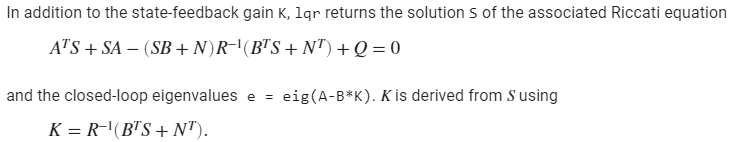

 

Compare matlab's Riccati equation for LQR, we get R_koopman = B_tranpose*inv(R_lqr)*B

Q = diag([0.001, 0.1, 0.0005, 0.1]); %cost on states
R_lqr = 1;
[K,P,CLP] = lqr(A,B,Q,R_lqr);
uLQR = @(x) -K*(x);

## HJ-Koopman Controller:

Where,

R_Koopman = B*inv(R_lqr)*B';
hat_R = W'*(R_Koopman)*W;
W1_inv = inv(W);
hat_Q = W1_inv*Q*W1_inv';
L = are(D,hat_R,hat_Q);

% control without scaling
uKoop=@(x) -inv(R_lqr)*Phi(x)'*L*DPhi(x)*g(0,x);

## Sanity Check 

L1 should be equal to P

L1 = W*L*W'

L1 = 	1.0e+06 *

    1.6860    0.6260    0.3401    0.1222
    0.6260    0.2330    0.1263    0.0454
    0.3401    0.1263    0.0686    0.0247
    0.1222    0.0454    0.0247    0.0089


P

P = 	1.0e+06 *

    1.6860    0.6260    0.3401    0.1222
    0.6260    0.2330    0.1263    0.0454
    0.3401    0.1263    0.0686    0.0247
    0.1222    0.0454    0.0247    0.0089


## Simulation

(change x_initial to simulate response of different initial conditions and plot)

deltaT = 0.01; %step-time
tspan = 0:deltaT:10;
options = odeset('RelTol',1e-9,'AbsTol',1e-300);
x_initial = [0.01,0,0,0];

%LQR
[tspan, xLQR] = ode45(@(t,x)f(t, x, uLQR(x)), tspan, x_initial, options);

if(abs(xLQR(end,1)) && abs(xLQR(end,3)) <=1e-3)
    disp('LQR succuess')
else
    disp('LQR failed')
end

LQR succuess


[tspan1, x_Koop] = ode45(@(t,x)f(t, x, uKoop(x)), tspan, x_initial, options);
if(abs(x_Koop(end,1)) && abs(x_Koop(end,3)) <=1e-3)
   disp('HJK succuess')
else
   disp('HJK failed')
end

HJK failed


## Plots

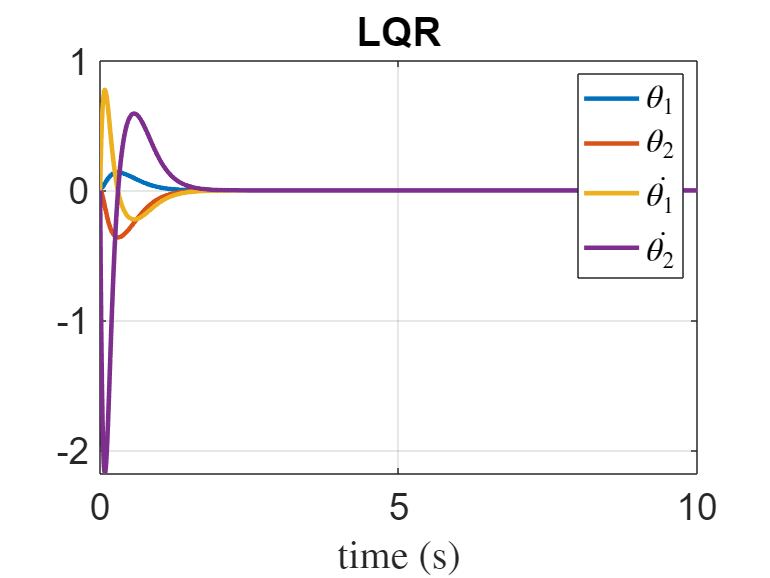

close all
figure(1)
%subplot(2,2,1)
plot(tspan, xLQR)
grid on;
title('LQR')
xlabel('time (s) ','interpreter','latex');
set(gca,'fontsize',20)
LEG = legend('$\theta_1$', '$\theta_2$', '$\dot{\theta_1}$','$\dot{\theta_2}$');
set(LEG,'interpreter','latex')

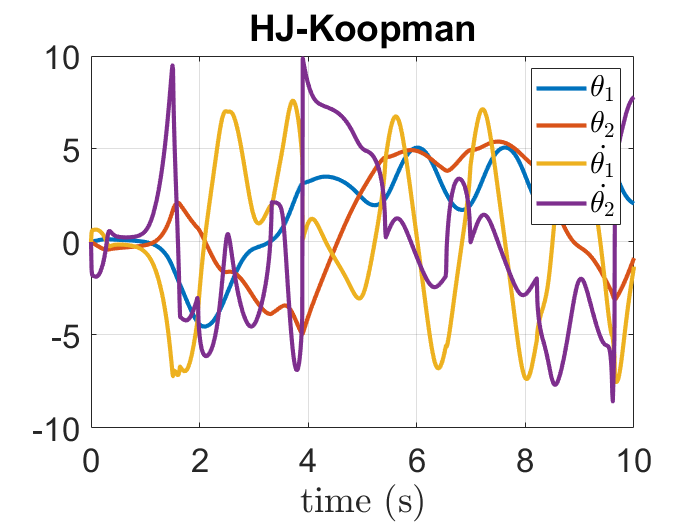

figure(2)
%subplot(2,2,2)
plot(tspan1, x_Koop)
grid on;
title('HJ-Koopman')
xlabel('time (s)','interpreter','latex');
%ylabel('$x_1$,$x_2$','interpreter','latex');
set(gca,'fontsize',20)
LEG = legend('$\theta_1$', '$\theta_2$', '$\dot{\theta_1}$','$\dot{\theta_2}$');
set(LEG,'interpreter','latex')

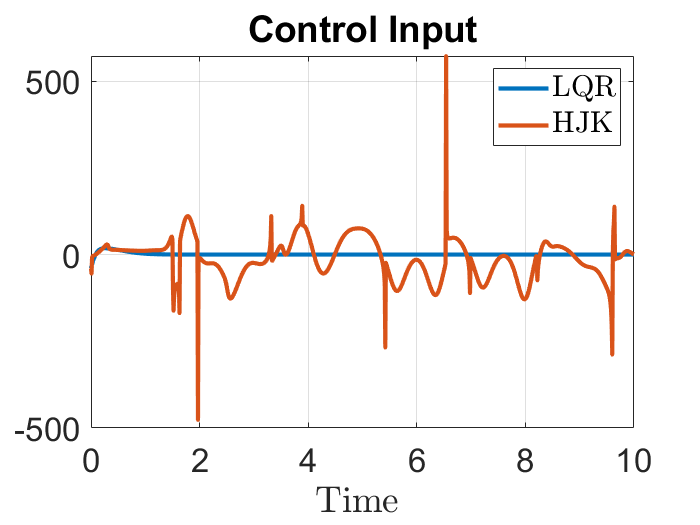

figure(3)
%subplot(2,2,3)
 U_Lqr =zeros(size(xLQR,1),1);
 U_Koop = zeros(size(xLQR,1),1);
for i=1:size(xLQR,1)
    U_Lqr(i) = uLQR(xLQR(i,:)');
    U_Koop(i) =uKoop(x_Koop(i,:)');
end
%plot(tspan, U_Lqr)
plot(tspan, U_Lqr, tspan1, U_Koop)
grid on;
title('Input')
xlabel('Time ','interpreter','latex');
set(gca,'fontsize',20)
LEG = legend('LQR','HJK');
set(LEG,'interpreter','latex')
title('Control Input')

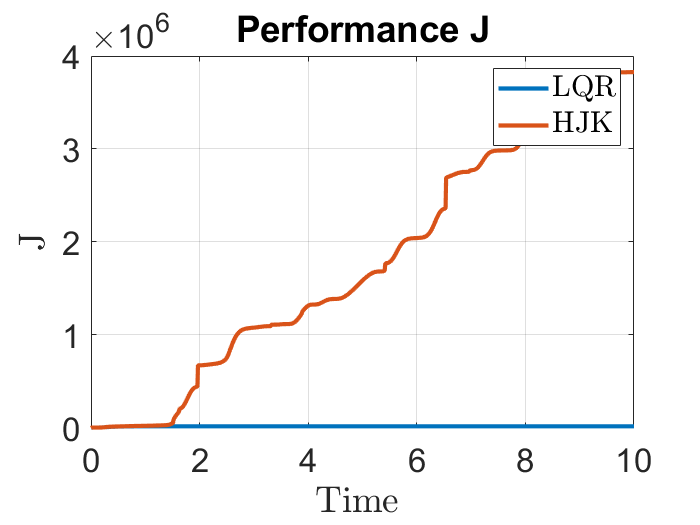

figure(4)
%subplot(2,2,4)
JLQR = cumsum(xLQR(:,1).^2 + xLQR(:,2).^2 + xLQR(:,3).^2 + xLQR(:,4).^2 + U_Lqr.^2);
Jkoopman =  cumsum(x_Koop(:,1).^2 + x_Koop(:,2).^2 + x_Koop(:,3).^2 + x_Koop(:,4).^2  +U_Koop.^2 );

plot(tspan, JLQR,tspan, Jkoopman)
grid on;
title('Performance J')
set(gca,'fontsize',20)
LEG =legend( 'LQR','HJK');
ylabel('J','interpreter','latex');
xlabel('Time ','interpreter','latex');
set(LEG,'interpreter','latex')

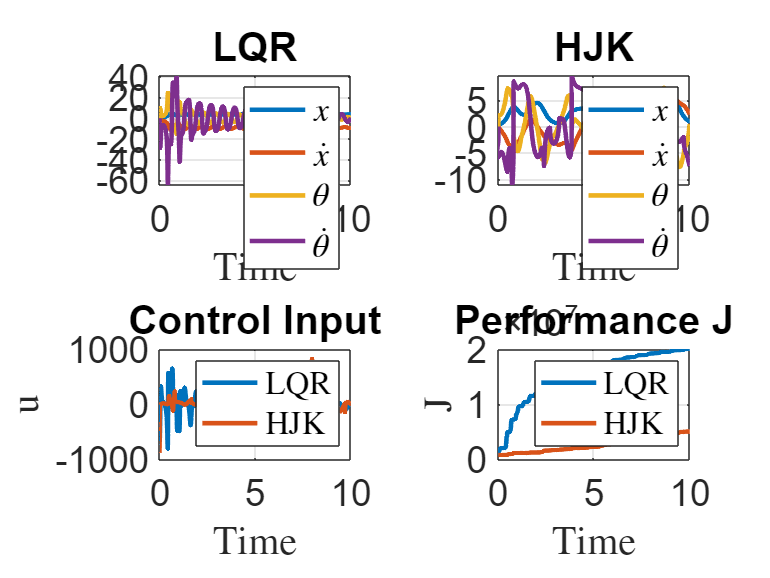

close all
subplot(2,2,1)
plot(tspan1, xLQR)
grid on; hold on;
%legend('x_1', 'x_2');xlabel('Time')
title('LQR')
xlabel('Time ','interpreter','latex');
%ylabel('$x_1$,$x_2$','interpreter','latex');
set(gca,'fontsize',20)
LEG = legend( '$x$', '$\dot{x}$', '$\theta$', '$\dot{\theta}$');
set(LEG,'interpreter','latex')

subplot(2,2,2)
plot(tspan1, x_Koop)
grid on;
title('HJK')
xlabel('Time','interpreter','latex');
%ylabel('$x_1$,$x_2$','interpreter','latex');
set(gca,'fontsize',20)
LEG = legend( '$x$', '$\dot{x}$', '$\theta$', '$\dot{\theta}$');
set(LEG,'interpreter','latex')

subplot(2,2,3)
 U_Lqr =zeros(size(xLQR,1),1);
 U_Koop = zeros(size(xLQR,1),1);
for i=1:size(xLQR,1)
    U_Lqr(i) = uLQR(xLQR(i,:)');
    U_Koop(i) =uKoop(x_Koop(i,:)');
end
plot(tspan, U_Lqr, tspan1, U_Koop)
grid on;
title('Input')
ylabel('u','interpreter','latex');
xlabel('Time ','interpreter','latex');
set(gca,'fontsize',20)
LEG = legend('LQR','HJK');
set(LEG,'interpreter','latex')
title('Control Input')

subplot(2,2,4)
JLQR = cumsum(xLQR(:,1).^2 + xLQR(:,2).^2 + xLQR(:,3).^2 + xLQR(:,4).^2 + U_Lqr.^2);
Jkoopman =  cumsum(x_Koop(:,1).^2 + x_Koop(:,2).^2 + x_Koop(:,3).^2 + x_Koop(:,4).^2  +U_Koop.^2 );
%plot(tspan, JLQR,)
plot(tspan, JLQR,tspan, Jkoopman)
grid on;
title('Performance J')
set(gca,'fontsize',20)
LEG =legend( 'LQR','HJK');
ylabel('J','interpreter','latex');
xlabel('Time ','interpreter','latex');
set(LEG,'interpreter','latex')

## Acrobot f(x)

function fg = Acrobot_F(t, x, u)

% system paramters
% m1 = 0.850; l1 = 0.154; lc1 = -0.0189; J1 = 6.25e-3; 
% m2 = 0.420; l2 = 0.210; lc2 = 0.0743; J2 = 4.48e-3;

mu1 = 5.50e-3; mu2 = 0.0125;
g = 9.801; n = 14/48; K_DC = 0.0160;

a1 = 0.0165; a2 = 0.0068; a3 = 0.0048;
b1 = 0.4758; b2 = 0.3057;

q1 = x(1,:); q2 = x(2,:); 
dq1 = x(3,:); dq2 = x(4,:);

m11 = a1 + a2 + 2*a3.*cos(q2);
m12 = a2 + a3.*cos(q2);
m22 = a2.*ones(1,size(x,2));
M = [m11 m12; m12 m22]; 


c11 = -a3.*dq2.*sin(q2);
c12 = -a3.*(dq1+dq2).*sin(q2);
c21 = a3.*dq1.*sin(q2);
c22 = zeros(1, size(x,2));
C = [c11.*dq1+c12.*dq2; c21.*dq1+c22.*dq2]; 


% G is negative for q1 = 0  about vertical
% G is positive for q1 = pi about vertical
g1 = -b1*sin(q1)-b2*sin(q1+q2);
g2 = -b2*sin(q1+q2); 
G = [g1; g2];
%B = [-mu1*dq1; n*K_dc*u-mu2*dq2];
dq = [dq1; dq2]; 

ddq = -M\(C+G+[mu1.*dq1; mu2.*dq2]);

f = [dq;ddq];
g = [0;0; M\[0; n.*K_DC]];
fg = f+g.*u;

end

## Acrobot g(x)

function g = Acrobot_g(t, x)

% system paramters
% m1 = 0.850; l1 = 0.154; lc1 = -0.0189; J1 = 6.25e-3; 
% m2 = 0.420; l2 = 0.210; lc2 = 0.0743; J2 = 4.48e-3;

mu1 = 5.50e-3; mu2 = 0.0125;
g = 9.801; n = 14/48; K_DC = 0.0160;

a1 = 0.0165; a2 = 0.0068; a3 = 0.0048;
b1 = 0.4758; b2 = 0.3057;
q1 = x(1,:); q2 = x(2,:); dq1 = x(3,:); dq2 = x(4,:);

m11 = a1 + a2 + 2*a3.*cos(q2);
m12 = a2 + a3*cos(q2);
m22 = a2*ones(1,size(x,2));
M = [m11 m12; m12 m22];

%g = [0;0; M\[zeros(1,size(x,2)); n*K_dc]];
g = [0;0; M\[0; n.*K_DC]];

end

## Monomial Basis

function [Psi, DPsi] = monomial_basis(deg, dim)
%  [Psi, DPsi] = monomial_basis(deg, dim) returns a monomial basis function and its derivative 
%   There is not a 1 included in Psi, only the linear and higher order terms
%   deg = degree of monomial
%   dim = number of states
k = linspace(2, deg, deg-1);
d = dim;

if (deg == 0)
    Psi = 0;
    for i=1:dim-1
        Psi = [Psi 0];
    end
    DPsi = zeros(dim,dim);
    Psi = Psi';
    
else

    x=sym('x',[d,1]);
    assume(x,'real')
    
    Psi = [x.'];
    for i=1:size(k,2)
        m = nchoosek(k(i)+d-1,d-1); 
        dividers = [zeros(m,1),nchoosek((1:(k(i)+d-1))',d-1),ones(m,1)*(k(i)+d)]; 
        a = diff(dividers,1,2)-1;
        for i = 1:size(a,1)
            Psi = [Psi prod(x.' .^ a(i,:))];
        end
    end
    DPsi = jacobian(Psi,x);
    
    
    Trig_terms = [];
    for j=1:dim-2
        Trig_terms = [Trig_terms sin(x(j)) cos(x(j))];
    end

    % Using trig terms for acrobot gives bad results compared to LQR
    %Psi = [Psi Trig_terms sin(x(1)+x(2)) cos(x(1)+x(2))]
    Psi
    Psi = Psi';

end

end

## Bernstein Basis

function [Psi,DPsi] = bernstein_basis(order, dim, scale)
%  [Psi, DPsi] = bernstein_basis(deg, dim,scale=0) returns a bernstein basis function and its derivative 
%   There is not a 1 included in Psi, only the linear and higher order terms
%   order = order of bernstein polynomials being fit
%   dim = number of states

if nargin<3
  scale = 0;
end

x=sym('x',[dim,1]);
assume(x,'real')
Psi = [];

if(order==0)
    Psi = 1;
end

for i = 0:order
    m = nchoosek(order,i);
    for j = 1:dim
        %Psi = [Psi; m.*((x(j)+1).^i * (-x(j)).^(order-i))];
        %scale to -2pi to 2pi
        Psi = [Psi; m.*((x(j)+scale).^i * (1-scale-x(j)).^(order-i))];
    end
end

DPsi = jacobian(Psi,x);

end